# ECE 480 EXAM #1 FALL 2022

Daniel Vijayasegar

UMID: 7688 3722

Major: Electrical Engineering, Senior

## PROBLEM #1

### PART A

% plotting continuous time signal and it's components
syms t
B = 5;
alpha = -4.462871e4;
x_a1_t = B*exp(alpha*t);

disp('Plot of x_a1(t) continuous time signal')

Plot of x_a1(t) continuous time signal


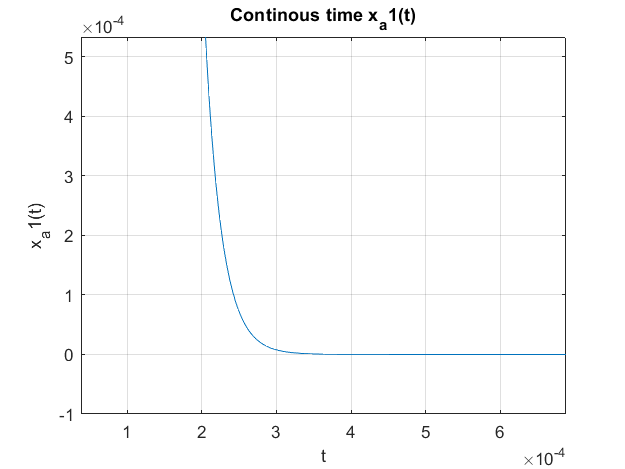

figure('Name','Problem 1A: x_a1(t)');
fplot(x_a1_t)
xlabel('t');
ylabel('x_a1(t)');
title('Continous time x_a1(t)');
xlim([0.000038 0.000688])
ylim([-0.000100 0.000533])
grid on;


f1 = 25000;  % sampling frequency
x_a2_t = sin(2*pi*f1*t + pi/2);

disp('Plot of x_a2(t) continuous time signal')

Plot of x_a2(t) continuous time signal


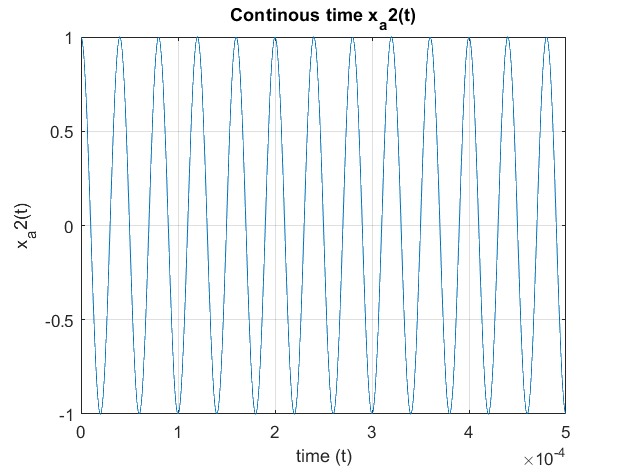

figure('Name','Problem 1A: x_a2(t)');
fplot(x_a2_t)
xlabel('time (t)');
ylabel('x_a2(t)');
title('Continous time x_a2(t)');
xlim([0 5e-4])
ylim([-1 1])
grid on;



x_at = x_a1_t*x_a2_t;

disp('Plot of x_a(t) continuous time signal')

Plot of x_a(t) continuous time signal


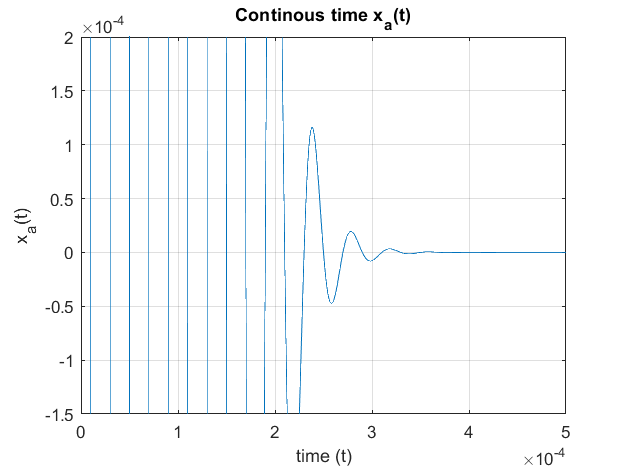

figure('Name','Problem 1A: x_a(t)');
fplot(x_at)
xlabel('time (t)');
ylabel('x_a(t)');
title('Continous time x_a(t)');
xlim([0 5e-4])
ylim([-1.5e-4 2e-4])
grid on;

I arbitrarily chose these viewing windows to more clearly show the behaviors of the three analog signals.

### PART B

%finding energy of x_a1(t) and average power of x_a2(t)

%energy of x_a1(t)
squared_signal1 = abs(x_a1_t)*abs(x_a1_t);
energy_x_a1_t = int(squared_signal1, 0, inf);   %applying energy formula: integrate abs value of signal squared over [0, inf]
disp('Energy of x_a1(t) = ');

Energy of x_a1(t) = 


energy_x_a1_t

$$energy\_x\_a1\_t = 2.8009e-04$$



%power of x_a2(t)
%peak #1 --> (0.00028, 1)
%peak #2 --> (0.00032, 1)
%period = peak to peak time

%applying avg power formula: integrate squared signal over one period, & divide by period
T = 0.00032-0.00028;
squared_signal2 = x_a2_t*x_a2_t;
disp('Average Power of x_a2(t) = ');

Average Power of x_a2(t) = 


avgpower_x_a2_t = (int(squared_signal2, 0, T))/T  

$$avgpower\_x\_a2\_t = 0.5000$$

For part 1B, I used the continuous time energy and average power formulae, with the steps implemented separately (i.e. squaring, then integrating in separate steps)

### PART C

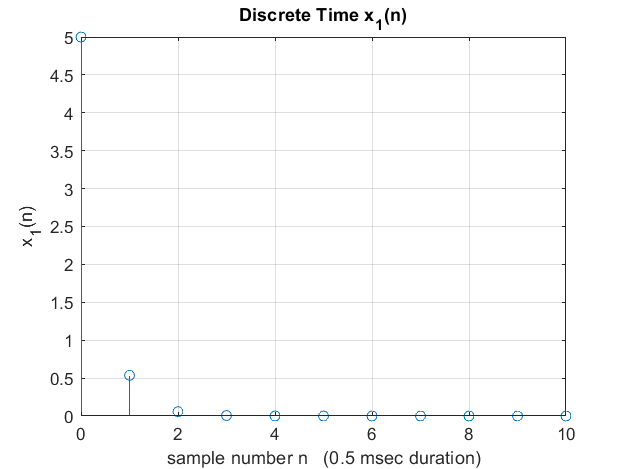

% Finding discrete time counterparts of signal & components

% Discretizing x_a1(t) to x_1(n)
fsamp=20000;
T=1/fsamp;
time=5e-4;
num_samples = time/T;
n=0:1:num_samples;

x1_n = B*exp(alpha*n*T);

figure('Name','Problem 1C: Discrete Time x_1(n)');
stem(n,x1_n);
xlabel('sample number n   (0.5 msec duration)');
ylabel('x_1(n)');
title('Discrete Time x_1(n)');
grid on;

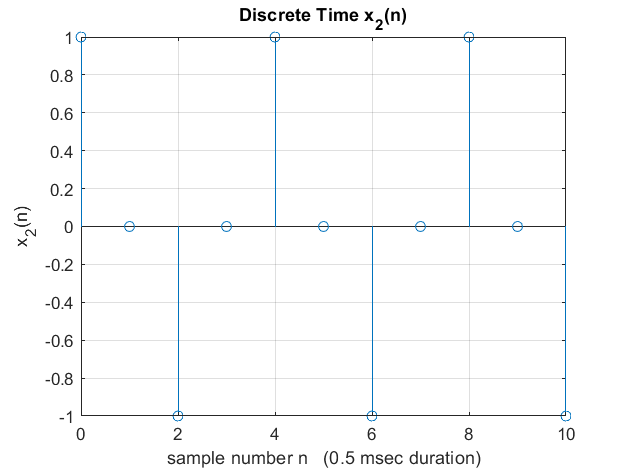




% Discretizing x_a2(t) to x_2(n)
x2_n = sin(2*pi*f1*n*T + pi/2);
figure('Name','Problem 1C: Discrete Time x_2(n)');
stem(n,x2_n);
xlabel('sample number n   (0.5 msec duration)');
ylabel('x_2(n)');
title('Discrete Time x_2(n)');
grid on;




% Discretizing x_a(t) to x(n)
x_n = (B*exp(alpha*n*T)).*sin(2*pi*f1*n*T + pi/2);
disp('x(n) = [B*exp(alpha*n*T)] * [sin(2*pi*f1*n*T + pi/2)]')

x(n) = [B*exp(alpha*n*T)] * [sin(2*pi*f1*n*T + pi/2)]


 To discretize the analog inputs, I replaced time 't' with n*T. T was calculated using the given Fsamp. I used a consistent time window (10 samples) for all three sampled signals.

### PART D

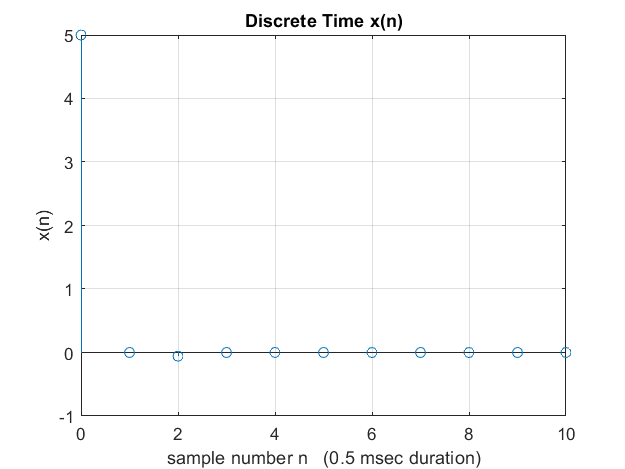

% Plotting x(n) and finding the energy

figure('Name','Problem 1C: Discrete Time x(n)');
stem(n,x_n);
xlabel('sample number n   (0.5 msec duration)');
ylabel('x(n)');
title('Discrete Time x(n)');
grid on;


disp('Energy of x(n): ')

Energy of x(n): 


energy=sum((abs(x_n)).^2)

energy = 25.0033

For part 1D, I used the discrete energy formula, summing the squared absolute values of all the samples in the time window.

### PART E

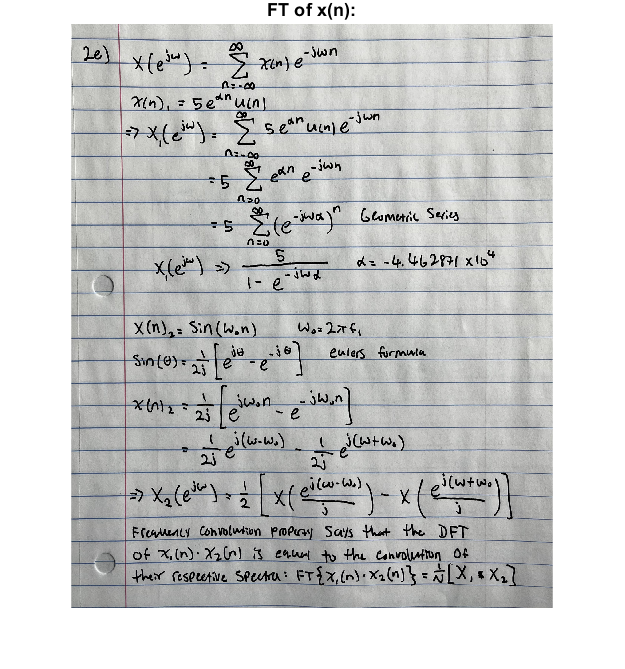

% Derive the fourier transform of x(n)

figure('Name','Problem 2E','NumberTitle','off');
imshow(imread("exam1_2e.jpg"))
title('FT of x(n):')

I started by computing the discrete fourier transforms of x1(n) and x2(n) separately. The frequency convolution property says that the fourier trasnform of the product of two sequences in the time domain is equivalent to the convolution of their respective spectra in the frequency domain. Convolving X1(e^jw) and X2(e^jw) would give the fourier transform of the sequence x(n).

### PART F

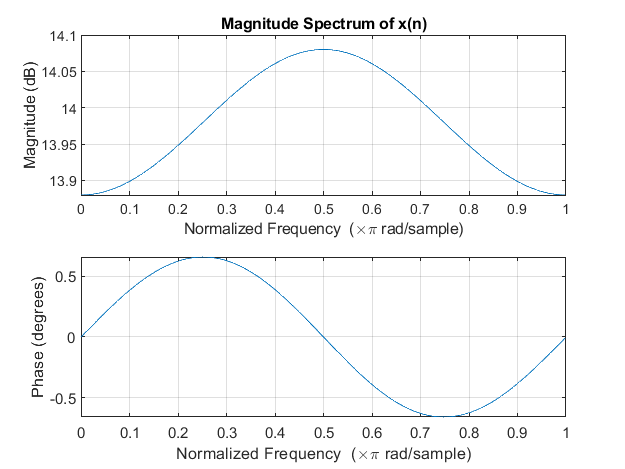

% Plot the magnitude spectrum of x(n)
figure('Name','Problem 1F: Magnitude Spectrum of x(n)');
freqz(x_n)
title('Magnitude Spectrum of x(n)');

I used the 'freqz' command to get the frequency response of x(n). 'freqz' plots the phase response as well even though I didn't need it.

## PROBLEM #2

### PART A

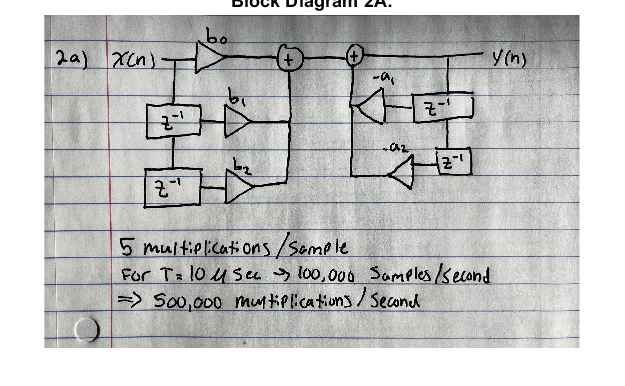

% Draw the block diagram, find number of multiplications/sec

figure('Name','Problem 2A','NumberTitle','off');
imshow(imread("exam1_2a.jpg"))
title('Block Diagram 2A:')


disp('From the block diagram:')

From the block diagram:


disp('5 multiplications/sample')

5 multiplications/sample


disp('For T=10 microsec --> 100,000 samples/second')

For T=10 microsec --> 100,000 samples/second


disp('Therefore --> 500,000 multiplications/second')

Therefore --> 500,000 multiplications/second


For part 2A, I wrote out the difference equation and constructed the block diagram by inspection. Z^-1 represents delays and the triangles represent coefficient multiplications. Since this is an IIR filter, past outputs y(n) are fed back in.

### PART B

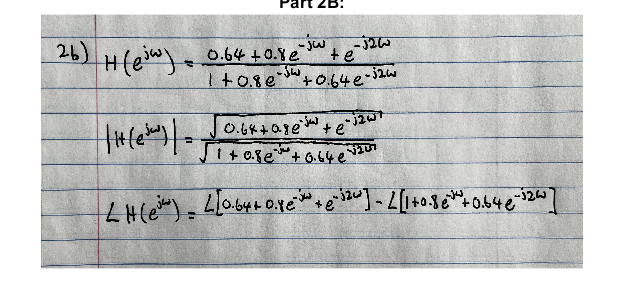

% Write expressions for frequency, magnitude, and phase responses

figure('Name','Problem 2A','NumberTitle','off');
imshow(imread("exam1_2b.jpg"))
title('Part 2B:')


syms w
%expressing frequency response below
numerator = 0.64 + 0.8*exp(-1i*w) + exp(-2i*w)

$$numerator = 0.8000\,{\mathrm{e}}^{-1\,w\,\mathrm{i}}+{\mathrm{e}}^{-2\,w\,\mathrm{i}}+0.6400$$

denominator = 1 + 0.8*exp(-1i*w) + 0.64*exp(-2i*w)

$$denominator = 0.8000\,{\mathrm{e}}^{-1\,w\,\mathrm{i}}+0.6400\,{\mathrm{e}}^{-2\,w\,\mathrm{i}}+1$$


freq_response = numerator/denominator

$$freq\_response = \frac{0.8000\,{\mathrm{e}}^{-1\,w\,\mathrm{i}}+{\mathrm{e}}^{-2\,w\,\mathrm{i}}+0.6400}{0.8000\,{\mathrm{e}}^{-1\,w\,\mathrm{i}}+0.6400\,{\mathrm{e}}^{-2\,w\,\mathrm{i}}+1}$$

mag_response = abs(freq_resp)

$$mag\_response = \frac{\left|0.8000\,{\mathrm{e}}^{-1\,w\,\mathrm{i}}+{\mathrm{e}}^{-2\,w\,\mathrm{i}}+0.6400\right|}{\left|0.8000\,{\mathrm{e}}^{-1\,w\,\mathrm{i}}+0.6400\,{\mathrm{e}}^{-2\,w\,\mathrm{i}}+1\right|}$$

phase_response = angle(mag_resp)

$$phase\_response = 0$$

In my written work, I was unable to simplify the expressions for magnitude response and phase response. I made an attempy at simplifying them using the matlab commands 'abs' for magnitude and 'angle' for phase.

### PART C

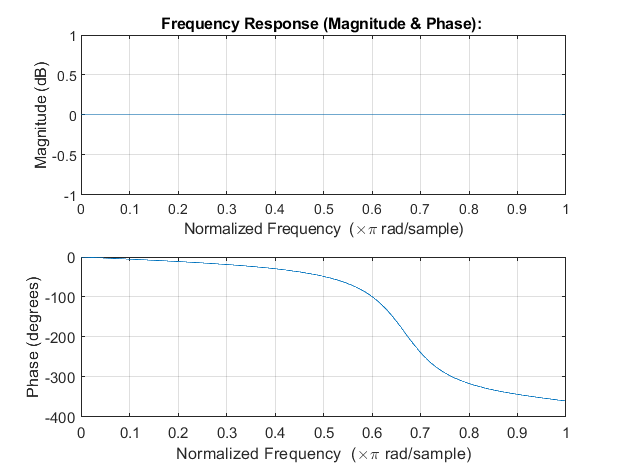

% Plot the magnitude response
b = [0.64, 0.8, 1];    %numerator x(n-i) coefficients
a = [1, 0.8, 0.64];    % denominator y(n-i) coefficients

figure('Name','Problem 2C','NumberTitle','off');
freqz(b,a)
title('Frequency Response (Magnitude & Phase): ')

Similar to part 1F, I used the 'freqz' command to get the frequency response of x(n). 'freqz' plots the phase response as well even though I didn't need it. The magnitude response I got is flat, meaning no frequency components are attenuated or amplified by the filter. Something must be wrong but I could not find the error, so I carried forward.

### PART D

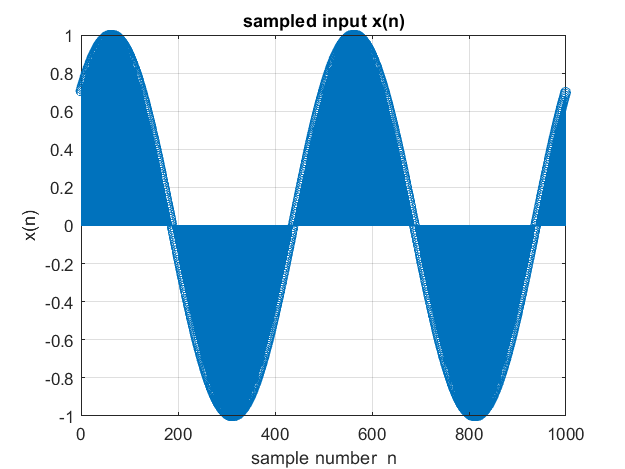


%% Find steady state output for sampled input x(n)

% Discretizing x_a(t) to x(n)
Tsamp = 10e-6;   %using Tsamp from part 2A
fsamp=1/Tsamp;
T=1/fsamp;
time=0.01;
num_samples = time/T;
n=0:1:num_samples;

f0 = 200;
x_n = cos(2*pi*f0*n*T - pi/4);

figure('Name','Problem 2D Input x(n)','NumberTitle','off');
stem(n,x_n);
title('sampled input x(n)')
xlabel('sample number  n')
ylabel('x(n)')
grid on;

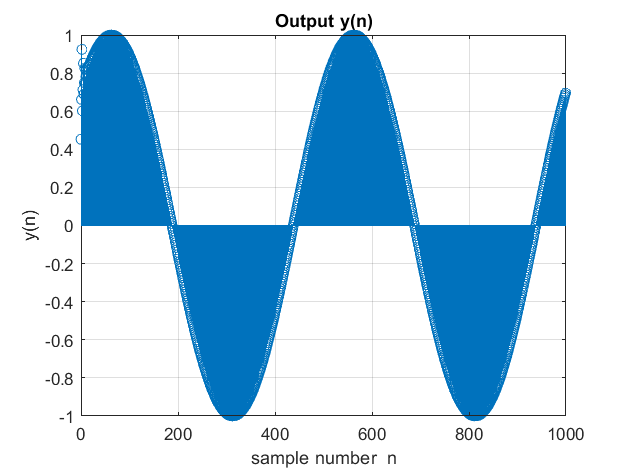


% Filtered output
y_n = filter(b,a,x_n);
figure('Name','Problem 2D output y(n)','NumberTitle','off');
stem(n,y_n);
title('Output y(n)')
xlabel('sample number  n')
ylabel('y(n)')
grid on;

My output y(n) for part 2D is not going to steady state. This is strange, since the problem specifically asks for steady state output, I would expect the filter to be stable. However it is possible that there is no steady state output since some IIR filters can be unstable if designed improperly. It is more likely that I made an error during a previous step. If the plot had shown SSO, then I would have used this code to calculate it: 

%SSO=mean[y(SSO_begin:(SSO_begin_index + arbitrarily long number of samples))];

This code averages the output y(n) over a period where the output is relatively stable

### PART E

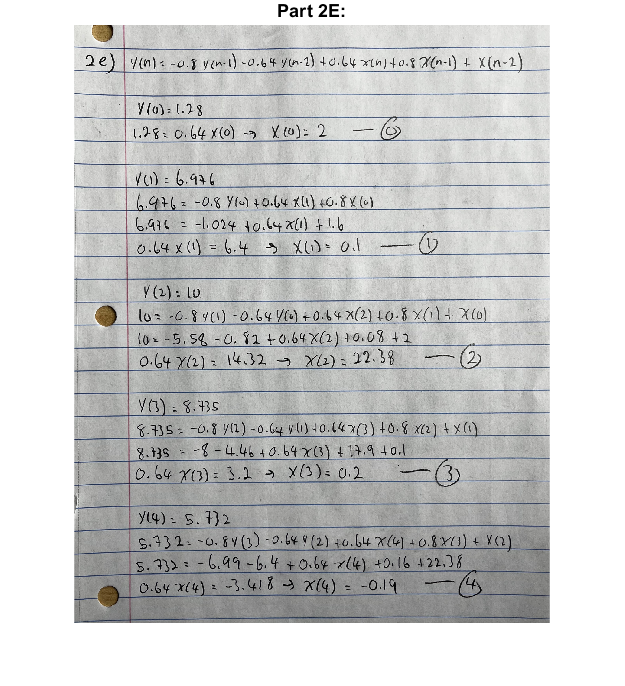

%Find the input values x(n) for n-->0:4
figure('Name','Problem 2A','NumberTitle','off');
imshow(imread("exam1_2e2.jpg"))
title('Part 2E:')